### **Иван Шаламов, 551 группа. Лабораторная работа № 4, 2020.**

% TODO: Разобраться с фазами и реализацией t(i).

clc;
close all;
clear;
opengl hardware;

### **Практическая часть.**

Начальные параметры.

TextSize = 15;

V = 1.005; % скорость переноса
Uinit = 1; % высота начальной ступеньки
xStartStep = 0.0; % координата от которой начинается ступенька
Lstep = 5.0; % ширина начальной ступеньки
xLeft = 0; % левая граница расчетной области
xRight = 100; % правая граница расчетной области
Courant = 0.9; % число Куранта

N = 101; % число узлов сетки
dh = (xRight - xLeft) / (N - 1); % шаг сетки
t_fin = 80.0; % время остановки

Создание сетки.

x = xLeft:dh:xRight;

Начальные условия. График первого приближения.

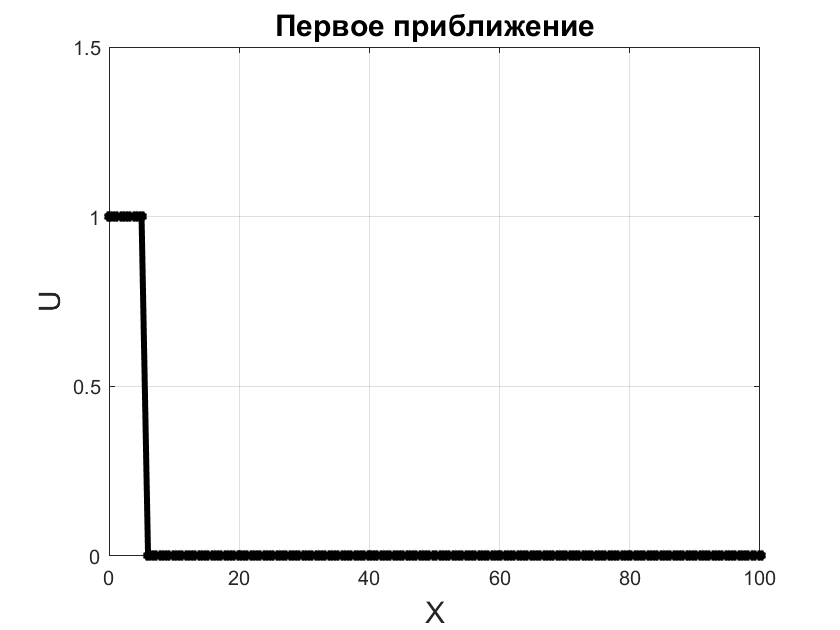

Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;

plot(x, Uold, '-k*', 'LineWidth', 3, 'MarkerSize', 5);
grid on;
title('Первое приближение', 'FontSize', TextSize);
xlabel('X', 'FontSize', TextSize);
ylabel('U', 'FontSize', TextSize);
xlim([xLeft, xRight]);
ylim([0, Uinit*1.5]);

pause(0.5);

Решение явной схемой "левый уголок". Схема применима при положительной скорости, условие устойчивости: КФЛ. Первый порядок аппроксимации по времени и пространственной координате. Courant = 0.9, V > 0.

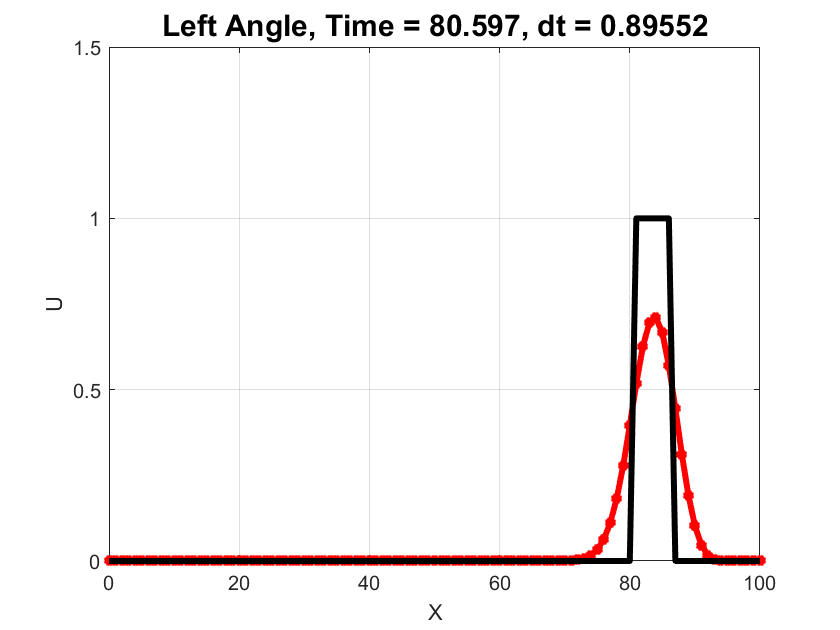

U_left1 = LeftAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

При отрицательной скорости переноса V схема "левый уголок" неприменима.

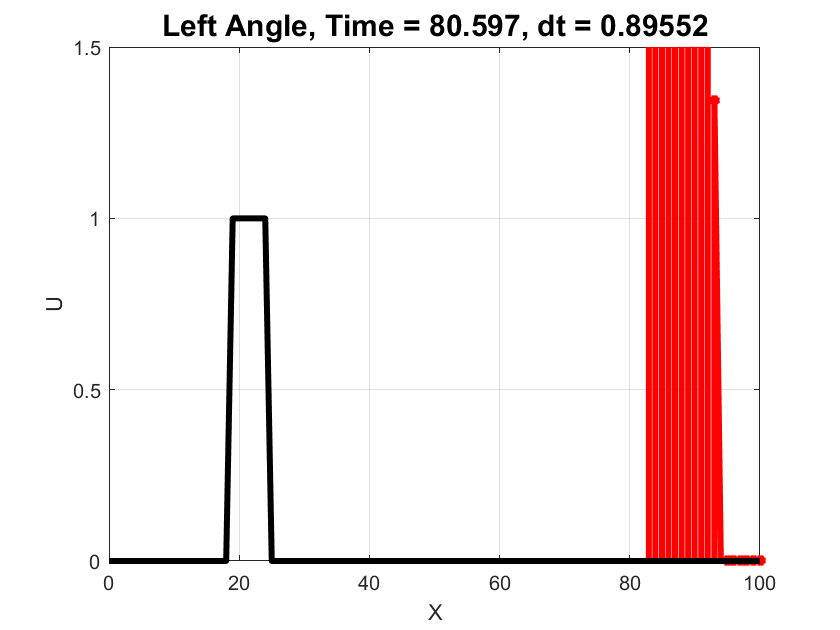

V = -1.005;

U_left2 = LeftAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

Можно заметить, что при уменьшении числа Куранта решение будет сглаживаться ("размазываться"). Это связано с наличием в выражении для погрешности аппроксимации четных производных решения, аналогичных вязким членам в уравнениях Навье-Стокса. Такие ошибки называются диссипацией разностной схемы, которая вносит в решение искусственную (схемную / численную) вязкость. 

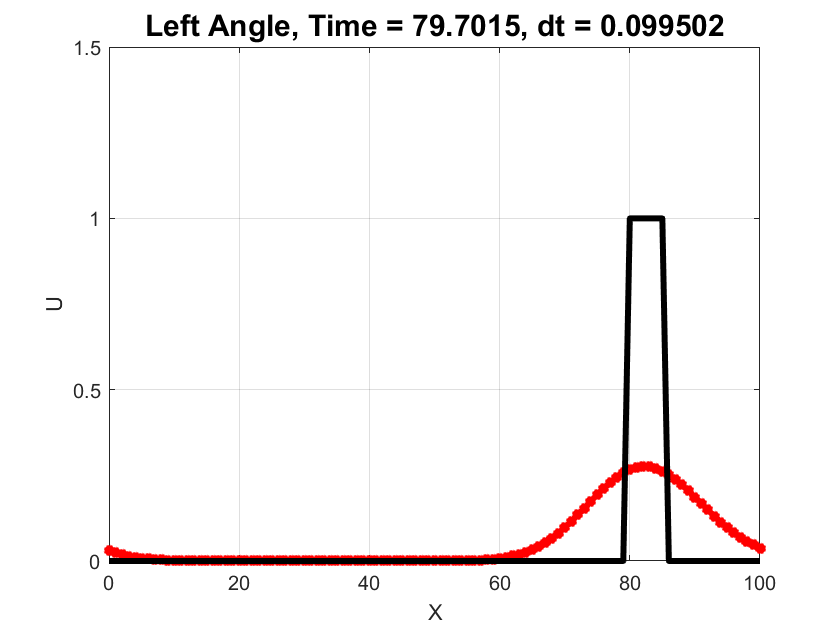

V = 1.005;
Courant = 0.1;

U_left3 = LeftAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

При числе Куранта > 1 нарушается условие устойчивости схемы "левый уголок" (КФЛ), решение "разваливается".

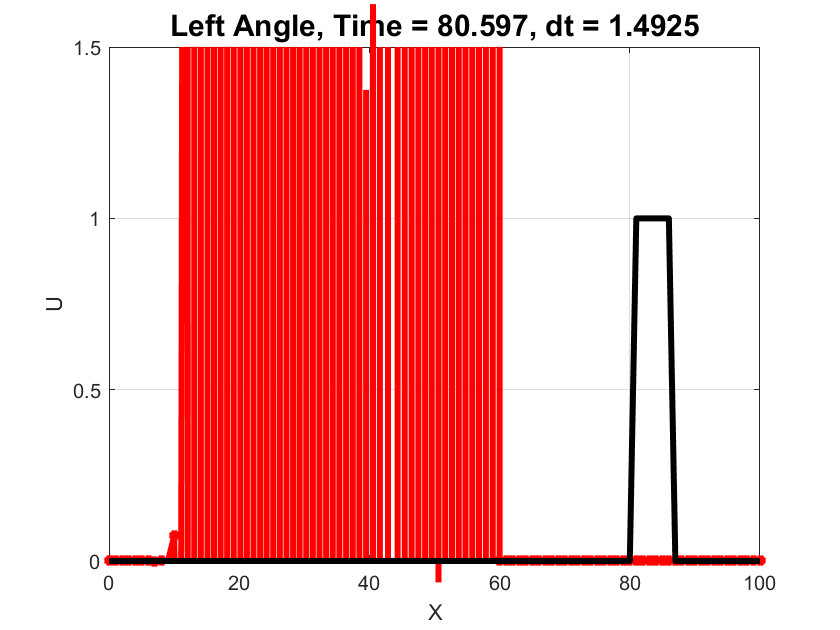

Courant = 1.5;

U_left4 = LeftAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

Решение явной схемой "правый уголок". Схема применима при отрицательной скорости, условие устойчивости: КФЛ. Первый порядок аппроксимации по времени и пространственной координате.

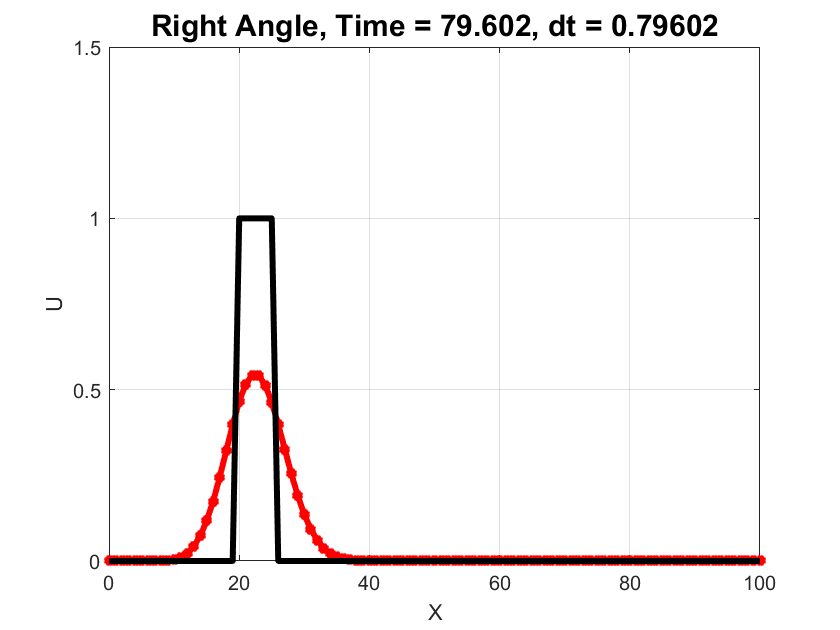

V = -1.005;
Courant = 0.8;

U_right = RightAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

### **Исследовательская часть.**

Решение явной схемой с разностями навстречу потоку. Схема применима при отрицательной и положительной скорости V, условие устойчивости: КФЛ. Первый порядок аппроксимации по времени и пространственной координате.

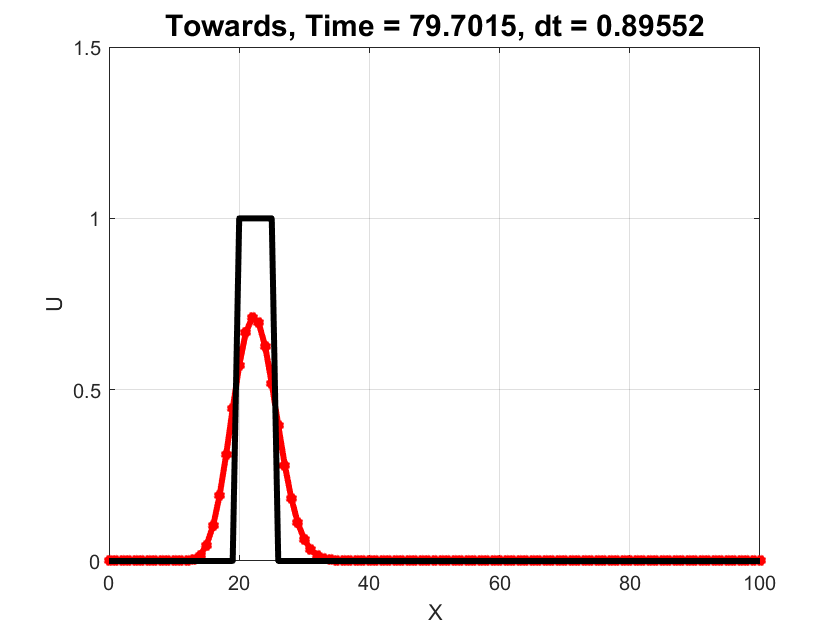

V = -1.005;
Courant = 0.9;

U_towards1 = Towards(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

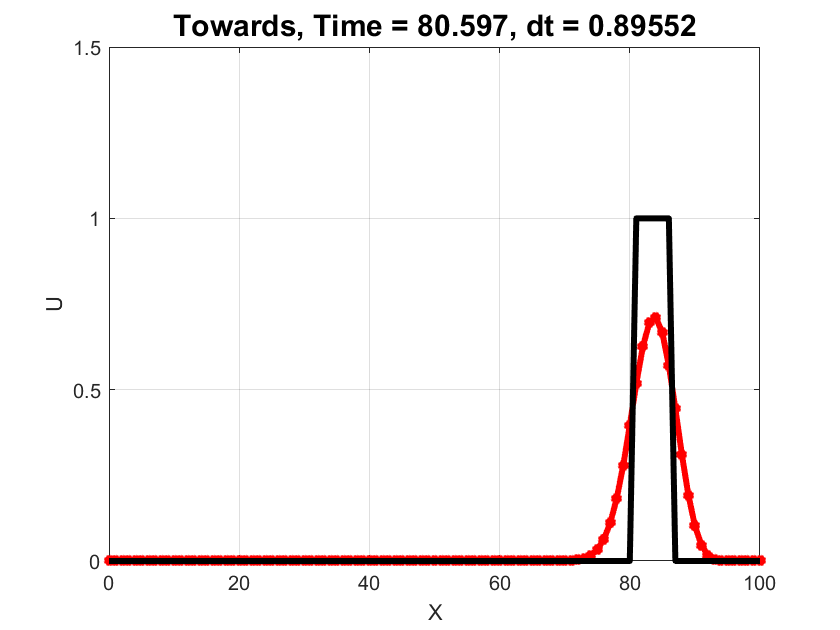

V = 1.005;

U_towards2 = Towards(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

Решение явной схемой с центральной разностью по пространственной переменной. В общем случае она неустойчива, что можно объяснить на основе свойств ее первого дифференциального приближения, в котором диссипативный член имеет отрицательный коэффициент схемной вязкости. Первый порядок аппроксимации по времени, второй по пространственной координате.

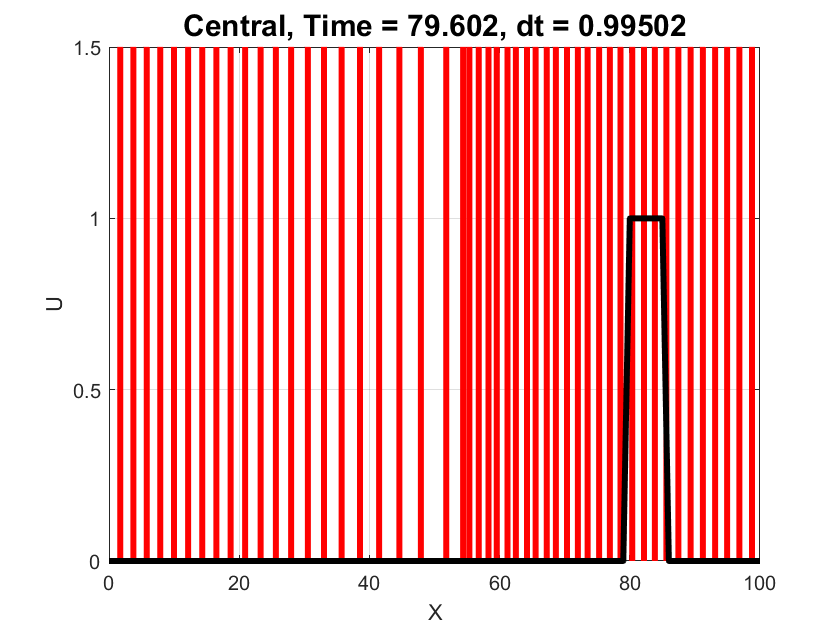

V = 1.005;
Courant = 1;

U_central = Central(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

Решение схемой Лакса. Схема применима при отрицательной и положительной скорости V, условие устойчивости: КФЛ. Ввиду специфического представления временной производной обладает значительной диссипацией. Первый порядок аппроксимации по времени, порядок аппроксимации по пространственной координате: dh^2 / dt.

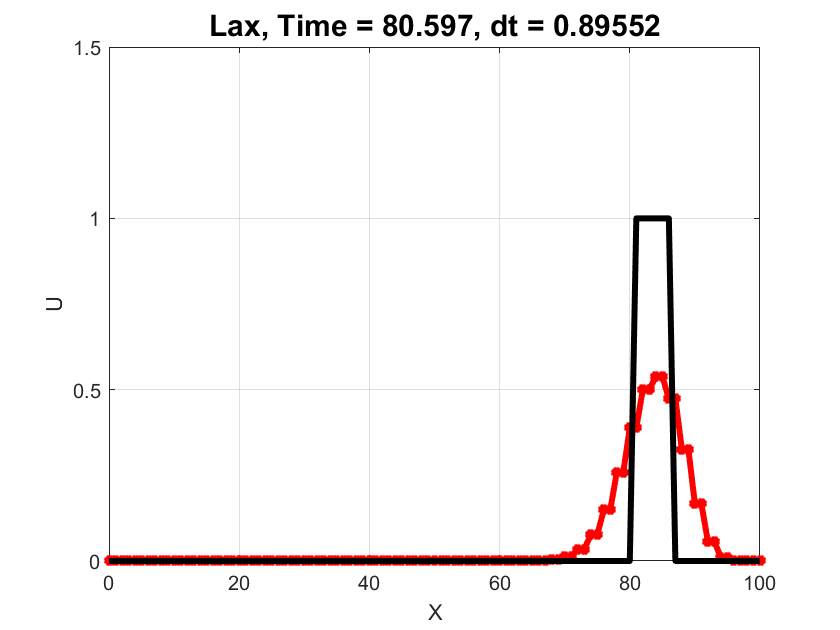

V = 1.005;
Courant = 0.9;

U_lax = Lax(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

Решение схемой Лакса — Вендроффа. Данная схема является схемой второго порядка как по времени, так и по пространственной переменной. Данная схема будет слабо "размазывать" решение, но в области его резкого изменения могут появляться нефизические осцилляции. Это связано с наличием в ее первом дифференциальном приближении дисперсионной составляющей с третьей производной. Однако в приближении уже не будут присутствовать диссипативные члены. Условие устойчивости: КФЛ.

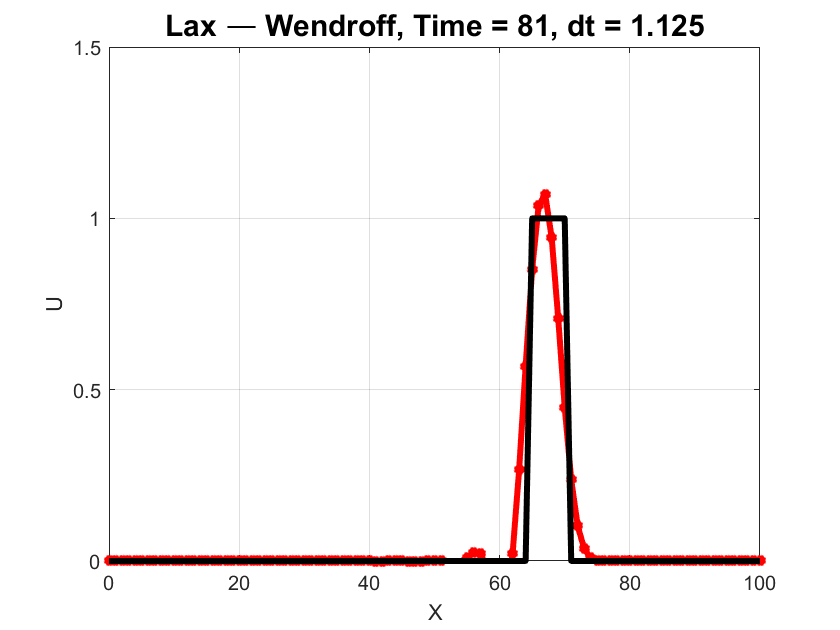

V = 0.8;
Courant = 0.9;

U_lw = LaxWendroff(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

Решение схемой Лакса — Вендроффа (двухшаговой). В смысле порядка аппроксимации и условия устойчивости она эквивалентна одношаговой схеме Лакса-Ведроффа, но двухшаговый вариант более удобен при проведении вычислений, поэтому именно с ним обычно связывается наименование данной разностной схемы.

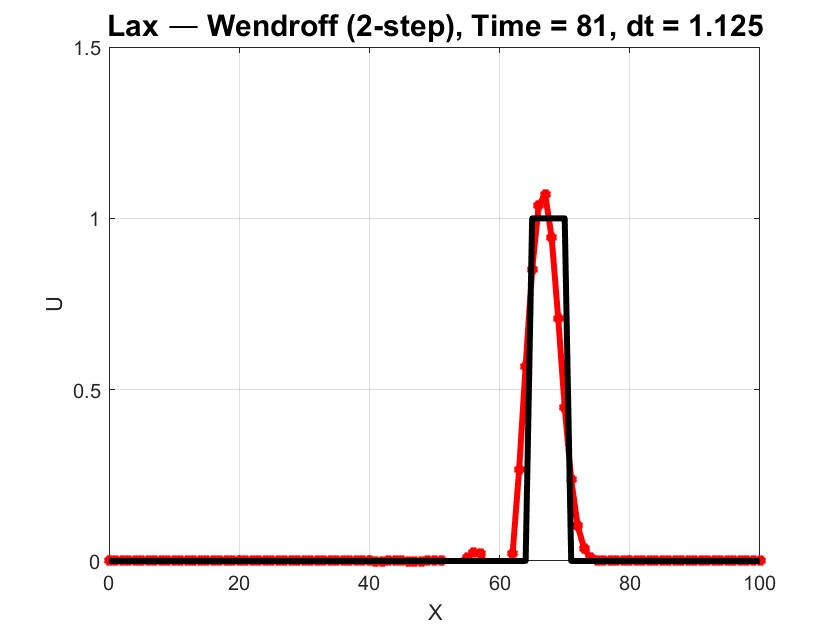

V = 0.8;
Courant = 0.9;

U_tslw = TwoStepLaxWendroff(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
    xRight, TextSize, t_fin);

Решение схемой Мак-Кормака. Для линейного уравнения переноса схема Мак-Кормака эквивалентна схеме Лакса — Вендроффа, поэтому они имеют одинаковые порядок аппроксимации и условие устойчивости.

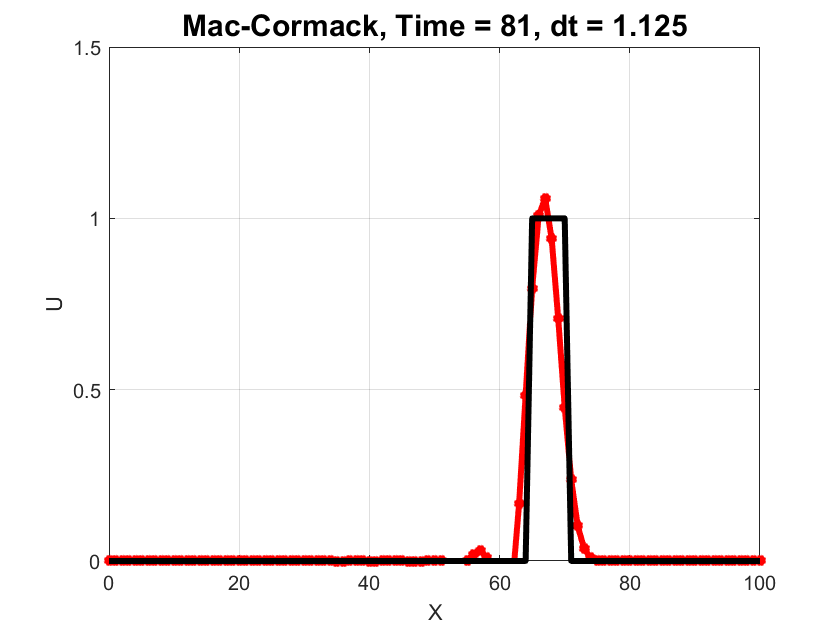

V = 0.8;
Courant = 0.9;

U_mc = MacCormack(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, xRight, ...
    TextSize, t_fin);

### **Использованные функции.**

Функция, строящая точное решение для линейного уравнения переноса со ступенькой с учетом переодических ГУ.

function U = Exact(x, t, V, Uinit, xStartStep, Lstep, xLeft, xRight)

    L = xRight - xLeft;
    n  = floor((xStartStep + V * t) / xRight);
    x1 = xStartStep + V * t - n * L;
    x2 = xStartStep + Lstep + V * t - n * L;

    if (x2 > xRight)
        
        x2 = xLeft + (x2 - xRight);
        U = f2(x, x1, x2, Uinit, xLeft, xRight);
        
    else
        
        U = f1(x, x1, x2, Uinit);
        
    end

end


function f1 = f1(x, x1, x2, Uinit)
    
    len = length(x);
    f1 = zeros(1, len);
    x_c = 0.5 * (x(1:end-1) + x(2:end));
    ind = find(x_c >= x1 & x_c <= x2);
    f1(ind) = Uinit;
    f1(ind+1) = Uinit;
    
end


function f2 = f2(x,x1,x2,Uinit,xLeft,xRight)
    
    len = length(x);
    f2 =  zeros(1, len);
    x_c = 0.5 * (x(1:end-1) + x(2:end));
    ind =  find(x_c >= x1 & x_c <= xRight);
    f2(ind) = Uinit;
    f2(ind+1) = Uinit;
    ind = find(x_c >= xLeft & x_c <= x2);
    f2(ind) = Uinit;
    
end

Явная схема "левый уголок".

function Uold = LeftAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 
        
        % Точное решение:
        Uexac = Exact(x, t(i+1), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема "левый уголок":
        Unew(2:end-1) = Uold(2:end-1) - V * dt / dh * (Uold(2:end-1) - Uold(1:end-2));
        
        % Периодические граничные условия:
        Unew(1) = Unew(1) - V * dt / dh * (Uold(1) - Uold(end));
        Unew(end) = Unew(end) - V * dt / dh * (Uold(end) - Uold(end-1));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Left Angle, ', 'Time = ', num2str(t(i+1)), ', dt = ', ...
                num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Явная схема "правый уголок".

function Uold = RightAngle(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 
        
        % Точное решение:
        Uexac = Exact(x, t(i), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема "правый уголок":
        Unew(2:end-1) = Uold(2:end-1) - V * dt / dh * (Uold(3:end) - Uold(2:end-1));
        
        % Периодические граничные условия:
        Unew(1) = Unew(1) - V * dt / dh * (Uold(2) - Uold(1));
        Unew(end) = Unew(end) - V * dt / dh * (Uold(1) - Uold(end));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Right Angle, ', 'Time = ', num2str(t(i)), ', dt = ', ...
                num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Явная схема с разностями навстречу потоку.

function Uold = Towards(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 

        % Точное решение:
        Uexac = Exact(x, t((V+abs(V))/(2 * V)*(i+1)+(V-abs(V))/(2 * V)*i), V, ...
            Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема "навстречу потоку":
        Unew(2:end-1) = Uold(2:end-1) - ...
            V * dt / (2 * dh) * (Uold(3:end) - Uold(1:end-2)) + ...
            abs(V) * dt / (2 * dh) * (Uold(1:end-2) - 2 * Uold(2:end-1) + Uold(3:end));
        
        % Периодические граничные условия:
        Unew(1) = Unew(1) - V * dt / (2 * dh) * (Uold(2) - Uold(end)) + ...
            abs(V) * dt / (2 * dh) * (Uold(end) - 2 * Uold(1) + Uold(2));
        Unew(end) = Unew(end) - V * dt / (2 * dh) * (Uold(1) - Uold(end-1)) + ...
            abs(V) * dt / (2 * dh) * (Uold(end-1) - 2 * Uold(end) + Uold(1));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Towards, ', 'Time = ', ...
                num2str(t((V+abs(V))/(2 * V)*(i+1)+(V-abs(V))/(2 * V)*i)), ...
                ', dt = ', num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Явная схема с центральной разностью по пространственной переменной.

function Uold = Central(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 

        % Точное решение:
        Uexac = Exact(x, t(i), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема "центральные разности":
        Unew(2:end-1) = Uold(2:end-1) - V * dt / (2 * dh) * (Uold(3:end) - Uold(1:end-2));
        
        % Периодические граничные условия:
        Unew(1) = Unew(1) - V * dt / (2 * dh) * (Uold(2) - Uold(end));
        Unew(end) = Unew(end) - V * dt / (2 * dh) * (Uold(1) - Uold(end-1));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Central, ', 'Time = ', num2str(t(i)), ', dt = ', ...
                num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Схема Лакса.

function Uold = Lax(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 

        % Точное решение:
        Uexac = Exact(x, t(i+1), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема Лакса:
        Unew(2:end-1) = ((Uold(3:end) + Uold(1:end-2)) / 2) - ...
            V * dt / (2 * dh) * (Uold(3:end) - Uold(1:end-2));
        
        % Периодические граничные условия:
        Unew(1) = ((Uold(2) + Uold(end)) / 2) - V * dt / (2 * dh) * (Uold(2) - Uold(end));
        Unew(end) = ((Uold(1) + Uold(end-1)) / 2) - ...
            V * dt / (2 * dh) * (Uold(1) - Uold(end-1));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Lax, ', 'Time = ', num2str(t(i+1)), ', dt = ', ...
                num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Схема Лакса — Вендроффа.

function Uold = LaxWendroff(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 

        % Точное решение:
        Uexac = Exact(x, t(i+1), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема Лакса — Вендроффа:
        Unew(2:end-1) = Uold(2:end-1) - ...
            V * dt / (2 * dh) * (Uold(3:end) - Uold(1:end-2)) + ...
            V^2 * dt^2 / (2 * dh^2) * (Uold(3:end) - 2 * Uold(2:end-1) + Uold(1:end-2));
        
        % Периодические граничные условия:
        Unew(1) = Unew(1) - V * dt / (2 * dh) * (Uold(2) - Uold(end)) + ...
            V^2 * dt^2 / (2 * dh^2) * (Uold(2) - 2 * Uold(1) + Uold(end));
        Unew(end) = Unew(end) - V * dt / (2 * dh) * (Uold(1) - Uold(end-1)) + ...
            V^2 * dt^2 / (2 * dh^2) * (Uold(1) - 2 * Uold(end) + Uold(end-1));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Lax — Wendroff, ', 'Time = ', num2str(t(i+1)), ', dt = ', ...
                num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Схема Лакса — Вендроффа (двухшаговая).

function Uold = TwoStepLaxWendroff(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;
    Uhalf1 = Uold;
    Uhalf2 = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 

        % Точное решение:
        Uexac = Exact(x, t(i+1), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема Лакса — Вендроффа (двухшаговая):
        
        % Первый шаг - предиктор (обеспечивает выполнение условий устойчивости):
        Uhalf1(2:end-1) = 0.5 * (Uold(3:end) + Uold(2:end-1)) - ...
            V * dt / (2 * dh) * (Uold(3:end) - Uold(2:end-1));
        Uhalf2(2:end-1) = 0.5 * (Uold(1:end-2) + Uold(2:end-1)) - ...
            V * dt / (2 * dh) * (Uold(2:end-1) - Uold(1:end-2));
        
        % Второй шаг - корректор (обеспечивает выполнение требуемой точности):
        Unew(2:end-1) = Uold(2:end-1) - V * dt / dh * (Uhalf1(2:end-1) - Uhalf2(2:end-1));
        
        % Периодические граничные условия:
        Uhalf1(1) = 0.5 * (Uold(2) + Uold(1)) - ...
            V * dt / (2 * dh) * (Uold(2) - Uold(1));
        Uhalf2(1) = 0.5 * (Uold(end) + Uold(1)) - ...
            V * dt / (2 * dh) * (Uold(1) - Uold(end));
        Uhalf1(end) = 0.5 * (Uold(1) + Uold(end)) - ...
            V * dt / (2 * dh) * (Uold(1) - Uold(end));
        Uhalf2(end) = 0.5 * (Uold(end-1) + Uold(end)) - ...
            V * dt / (2 * dh) * (Uold(end) - Uold(end-1));
        
        Unew(1) = Unew(1) - V * dt / dh * (Uhalf1(1) - Uhalf2(1));
        Unew(end) = Unew(end) - V * dt / dh * (Uhalf1(end) - Uhalf2(end));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Lax — Wendroff (2-step), ', 'Time = ', num2str(t(i+1)), ...
                ', dt = ', num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end

Схема Мак-Кормака.

function Uold = MacCormack(x, V, Courant, dh, Uinit, xStartStep, Lstep, xLeft, ...
        xRight, TextSize, t_fin)
    
    i = 1; % итерационный индекс элементов
    t(i) = 0; % статистика  времени (от итераций)
    dt = Courant * dh / abs(V); % шаг по времени
    plot_interval = round(1 / dt); % интервал вывода графиков
    plot_time = 1; % итерационный индекс графиков
    
    % Первое приближение:
    Uold = (x >= xStartStep & x <= (xStartStep + Lstep)) * Uinit;
    Unew = Uold;
    Upred = Uold;

    while t(i) <= t_fin
        
        % Время итерации:
        t(i+1) = t(i) + dt; 

        % Точное решение:
        Uexac = Exact(x, t(i+1), V, Uinit, xStartStep, Lstep, xLeft, xRight);
        
        % Схема Мак-Кормака (двухшаговая):
        
        % Первый шаг - предиктор (находится оценка величины U на (n+1)-м шаге 
        % по времени, используются разности назад):
        Upred(2:end-1) = Uold(2:end-1) - V * dt / dh * (Uold(2:end-1) - Uold(1:end-2));
        
        % Второй шаг - корректор (определяется окончательное значение U на (n+1)-м шаге 
        % по времени, используются разности вперед):
        Unew(2:end-1) = 0.5 * (Uold(2:end-1) + Upred(2:end-1)) - ...
            V * dt / (2 * dh) * (Upred(3:end) - Upred(2:end-1));
        
        % Периодические граничные условия:
        Upred(1) = Uold(1) - V * dt / dh * (Uold(1) - Uold(end));
        Upred(end) = Uold(end) - V * dt / dh * (Uold(end) - Uold(end-1));
        
        Unew(1) = 0.5 * (Uold(1) + Upred(1)) - V * dt / dh * (Upred(2) - Upred(1));
        Unew(end) = 0.5 * (Uold(end) + Upred(end)) - ...
            V * dt / dh * (Upred(1) - Upred(end));
    
        % Конец тела цикла:
        Uold = Unew;

        % График изменения решения:
        if i == plot_time
            
            plot_time = plot_time + plot_interval;
            figure(1), clf;
            plot(x, Uold, '-r*', x, Uexac, '-k', 'LineWidth', 3, 'MarkerSize', 5);
            grid on;
            title(['Mac-Cormack, ', 'Time = ', num2str(t(i+1)), ', dt = ', ...
                num2str(dt)], 'FontSize', TextSize);
            xlabel('X');
            ylabel('U');
            xlim([xLeft, xRight]);
            ylim([0, Uinit*1.5]);
            pause(0.05);
            
        end

        i = i + 1;

    end
    
end